***Ejercicio 1:***

Halle la recta de regresion de la nube de puntos dada.

% Nube de puntos
X = [13 14 15 16 17 18]

X =     13    14    15    16    17    18


Y = [18 18 17 16 15 14] 

Y =     18    18    17    16    15    14


[A, B] = lsline0 (X, Y) % A y B son los coeficientes de la

A = -0.8571

B = 29.6190

% recta de regresion

la recta es de la forma y= -0.8571*x+29.619

*Calculando el error...*

sum((polyval([A B], X)-Y).^2) % Calculo del error:

ans = 0.4762

% Valor calculado-real todo al cuadrado y se suma

***Ejercicio 2:***

Considere los datos y halle:

a) Halle polinomio de regresion optimo de grado 2 y grado 5 en sentido de minimo cuadrados

b) Halle la curva y=1/(Ax+B) que mejor se ajusta en el sentido de minimos cuadrados para el conjunto de datos.

***Solucion:***

**a) **

X = [-0.5 1 2 4 5]

X =    -0.5000    1.0000    2.0000    4.0000    5.0000


g = @(x) (atan(x))./(exp(-2*x)+3)

g = function_handle with value:
    @(x)(atan(x))./(exp(-2*x)+3)


Y = g(X) % Conjunto de datos

Y =    -0.0811    0.2505    0.3668    0.4419    0.4578


Ahora, para calcular el polinomio de grado dos se tiene que:

C = lspoly (X, Y, 2) % X,Y vector datos

C =    -0.0272
    0.2155
    0.0431


% M es el grado del polinomio a ajustar (Tercer componente)

Entonces el polinomio de regresion es el que se construye con los componentes de C y queda de la siguiente manera:

0.1090*x^2-1.2995*x+3.9775 

***calculemos su error:***

sum((polyval(C,X)-Y).^2) % Calculo del error

ans = 0.0015

Finalmente, grafiquemos.

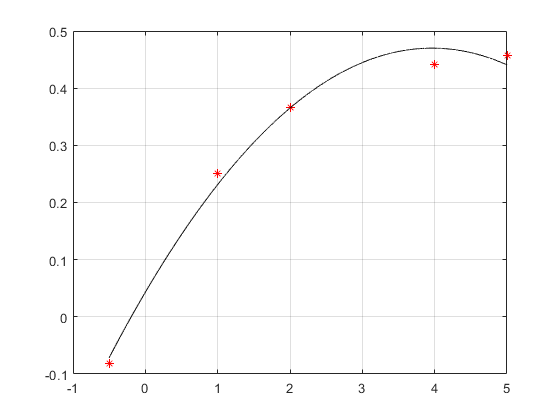

plot(X,Y, "*r")
hold on 
grid on
xx= linspace(X(1),X(end),10000);
yy = (polyval(C,xx));
plot(xx,yy,"k")

Para el polinomio de gtrado 5 se hace exactamente igual y se calcula todo igual, nos damos cuenta que el polinomio de grado 5 tiene un error mas pequeño

B)

Para este ejercicio el cambio de variable a realizar es con 1/y, asi:

C2 = lspoly(X,1./Y,1) % Ambos codigos sirven para calcular polinomio regre

C2 =     0.1562
    0.4219


[A B] = lsline0(X,1./Y)

A = 0.1562

B = 0.4219

Ahora, la curva de regresion TRANSFORMADA  va a ser 

Y* = 0.1562x + 0.4219

Grafiquemos:

yyc = 1./polyval([A B], xx)

yyc = 	1.0e+04 *

   -0.0021   -0.0021   -0.0021   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024


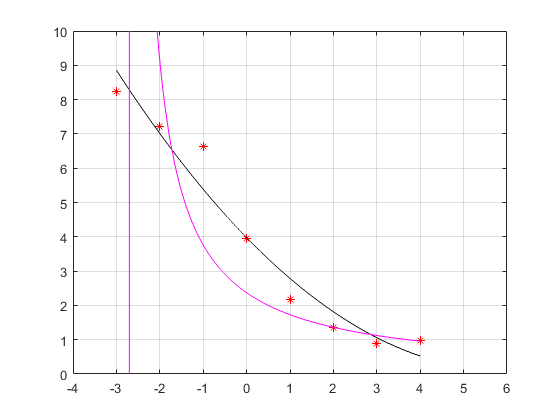

plot(xx,yyc,"m")
axis([-4 6 -0 10])

hold off

En apariencia, esta nueva curva parece tener un error mas grande:

sum((1./polyval([A B], X)-Y).^2) % En efecto, este error es muy grande. 

ans = 892.3759

% 892.3759
